*Will Reynolds (will.reynolds@mclaren.com), 2017*

This tutorial will first show you the value of the simplest Kalman filter, then walk through the terminology and the equations used for the rest of this tutorial. Once you are comfortable with the general approach of a linear Kalman filter (KF) and familiar with the terms, the next filter algorithms will be introduced and demonstrated in turn.

# Kalman Filter Tutorial

# Setting Up a Simple Tracking Problem

In order to show the value of the Kalman filter, let's look at a very simple example; a train moving along a straight track at constant velocity. We wish to estimate the states of the train every $\mathrm{dt}$ seconds. I am going to choose the following state vector, $x$, to define the system behaviour at each time step, $k$:

$x_k = \left[ \begin{array}{c}
p_k\\
v_k\\
\end{array} \right]$ , where $p$ is position along the track (m), and $v$ is velocity at which the train is moving (m/s). Given our understanding of the system dynamics, we can say that $p_{k+1} = p_{k} + v_k.\mathrm{dt}$ and $v_{k+1} = v_k$. This can be written as the following matrix algebra equation.


$$x_{k} = F.x_{k-1}=  \left[ \begin{array}{cc}
1 & \mathrm{dt}\\
0 & 1\\
\end{array} \right]. x_{k-1}$$


Now, in almost any situation, our state update will not be this idealised. We will typically have random disturbances to our system, which is called **process noise**, which for a train could be small changes in speed caused by wind buffeting. In this example we are modelling this as a Gaussian noise random variable, $v_k$, centred around 0m/s, with variance 0.01m/s.


$$x_{k} = F.x_{k-1}=  \left[ \begin{array}{cc}
1 & \mathrm{dt}\\
0 & 1\\
\end{array} \right]. x_{k-1} + v_k$$


The measurement which we have available to obtain of the train is pure position. This measurement, $y_k$, can therefore be written in matrix algebra as:


$$y_k = H.x_k = \left[ \begin{array}{cc}
1 & 0\\
\end{array} \right].  \left[ \begin{array}{c}
p_k\\
v_k\\
\end{array} \right]$$
 

Again, however, it is not likely that a measurement will be perfect. Typially there will at least be electromagnetic noise effects on the signal. Any noise on the measurement is imaginatively called **measurement noise**. In this example, we are modelling this as a Gaussian noise random variable, $w_k$, centred around 0m, with variance 0.1m.

The true initial confitions at time $k=0$ are $x_0 = \left[ \begin{array}{c}
p_0\\
v_0\\
\end{array} \right] = \left[ \begin{array}{c}
0\\
10\\
\end{array} \right]$. However, we are going to start with the erroneous estimate of $\hat{x}_0 = \left[ \begin{array}{c}
0\\
5\\
\end{array} \right]$.

# Demonstrating the Value

So, we have now set up the problem. We have a train getting buffeted with wind moving at roughly 10m/s along a straight track with noisy measurements of its position. Let's take a look at tracking its position and velocity. Let's first off look at two extremes of tracking methods; just using a model, and just using measurements.

Using just the model, we end up being affected by the initial conditions hugely and have no hope of closing the error in position or velocity. 

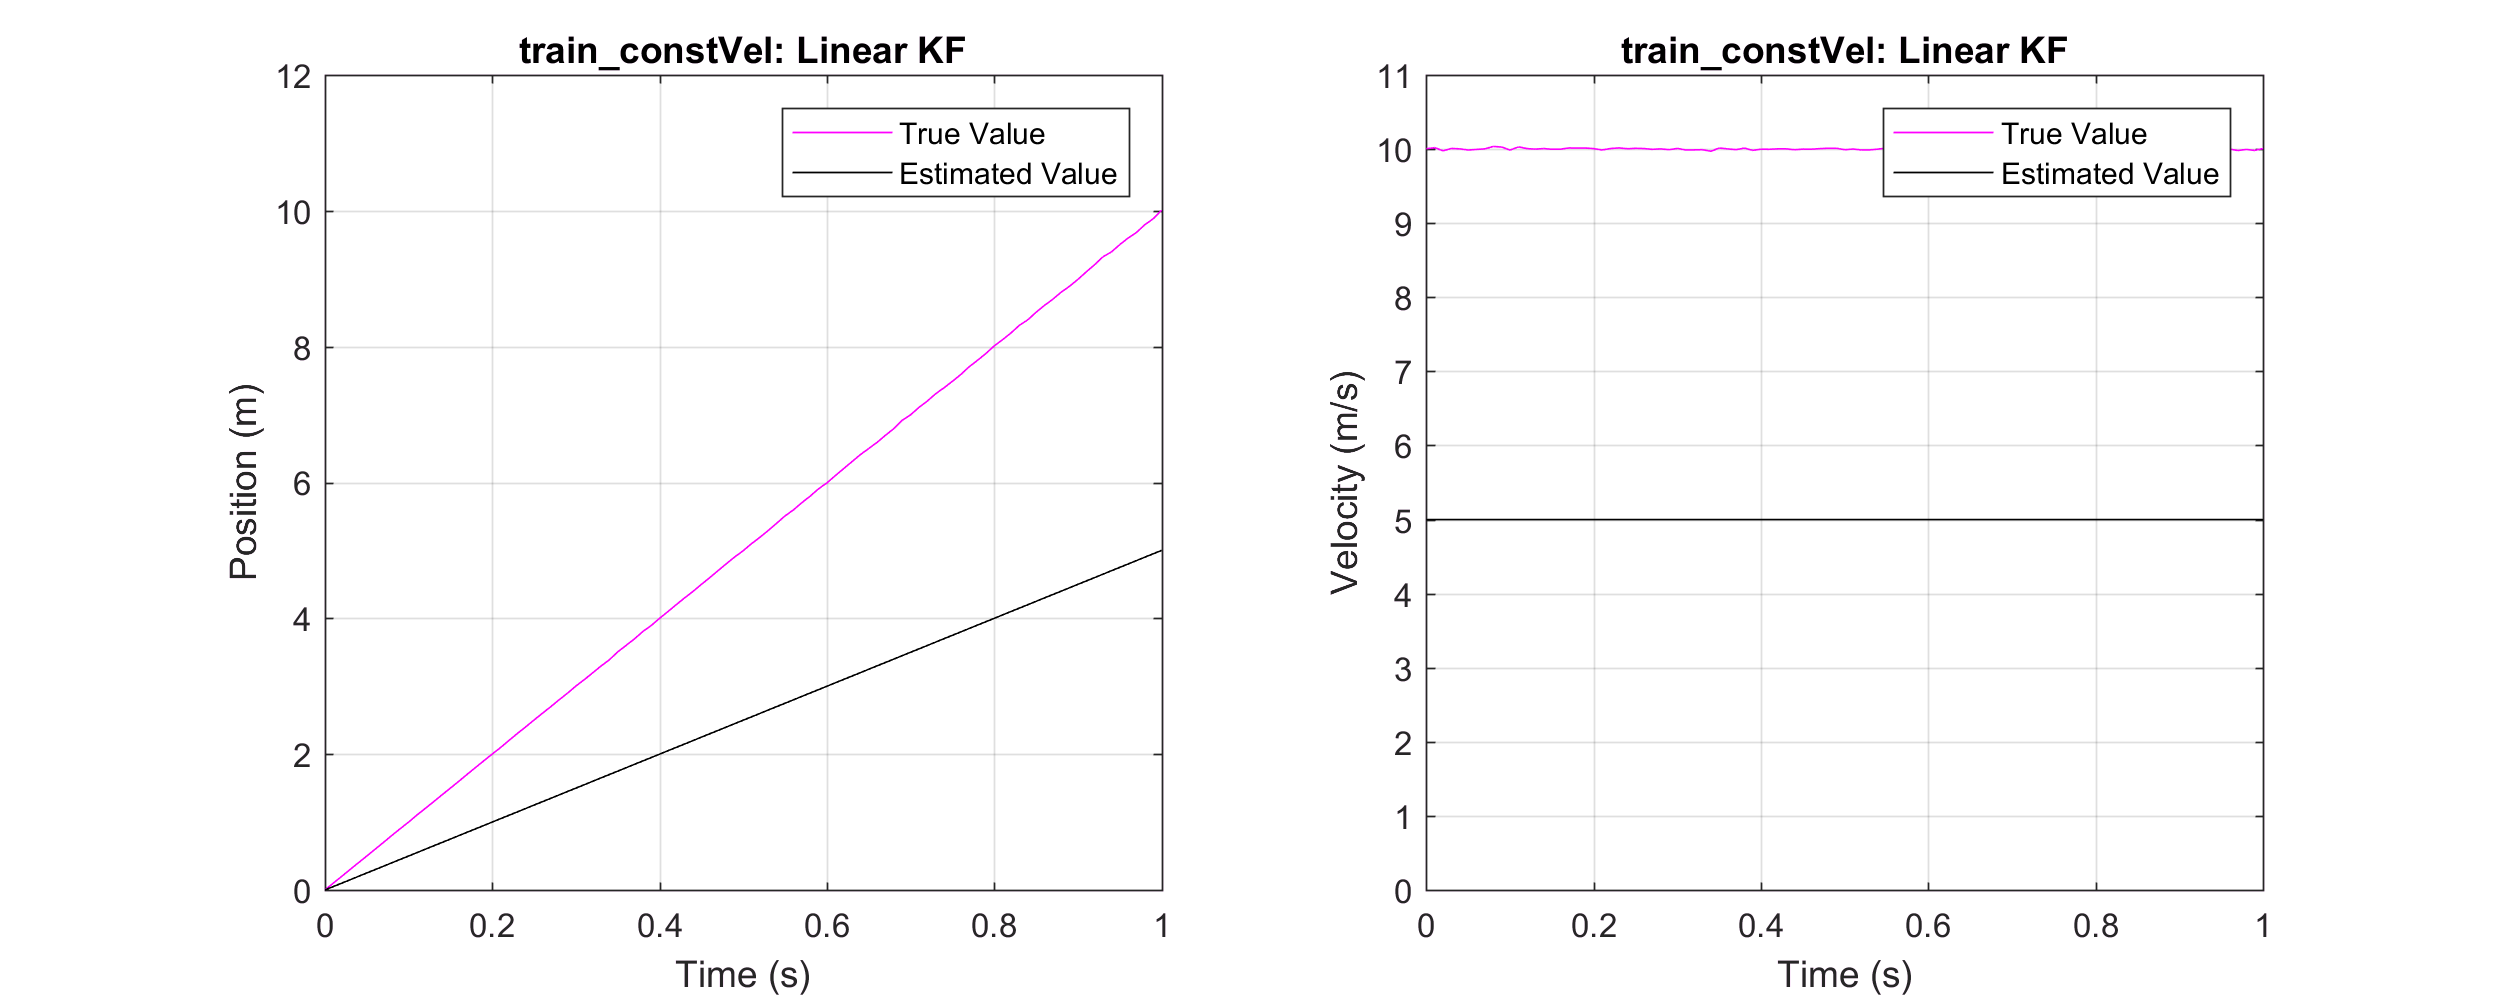

open('ModelOnly.fig')
set(gcf,'Position',[0 0 1000 400]);

Using just the measurements, we end up at the mercy of the large noise levels and have to infer velocity from this noisy measurement.

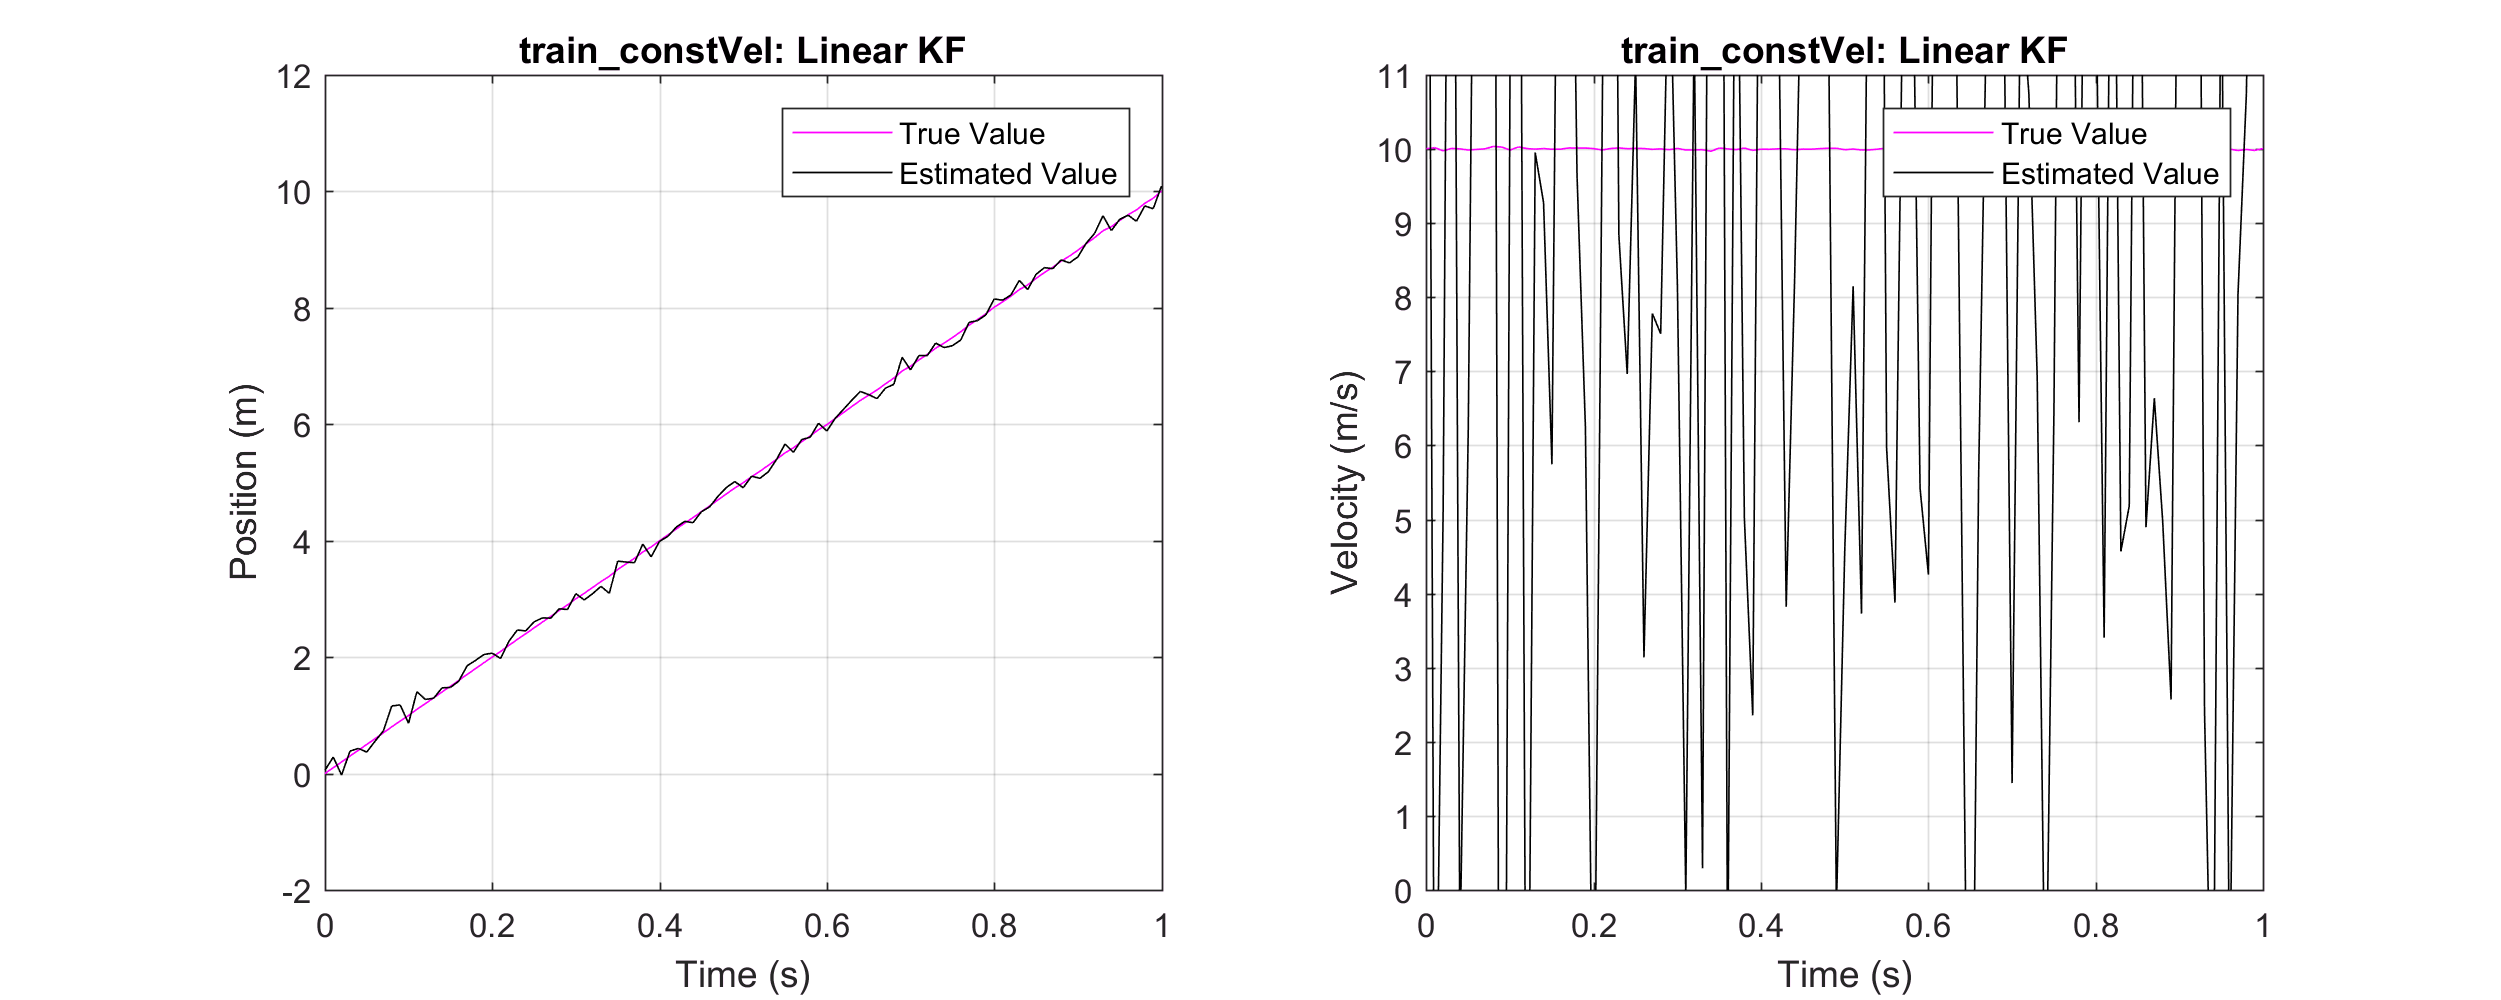

open('MeasurementOnly.fig')
set(gcf,'Position',[0 0 1000 400]);

However, if we implement a simple Kalman filter using our imperfect model of the system and our noisy position measurements, we are able to achieve the following:

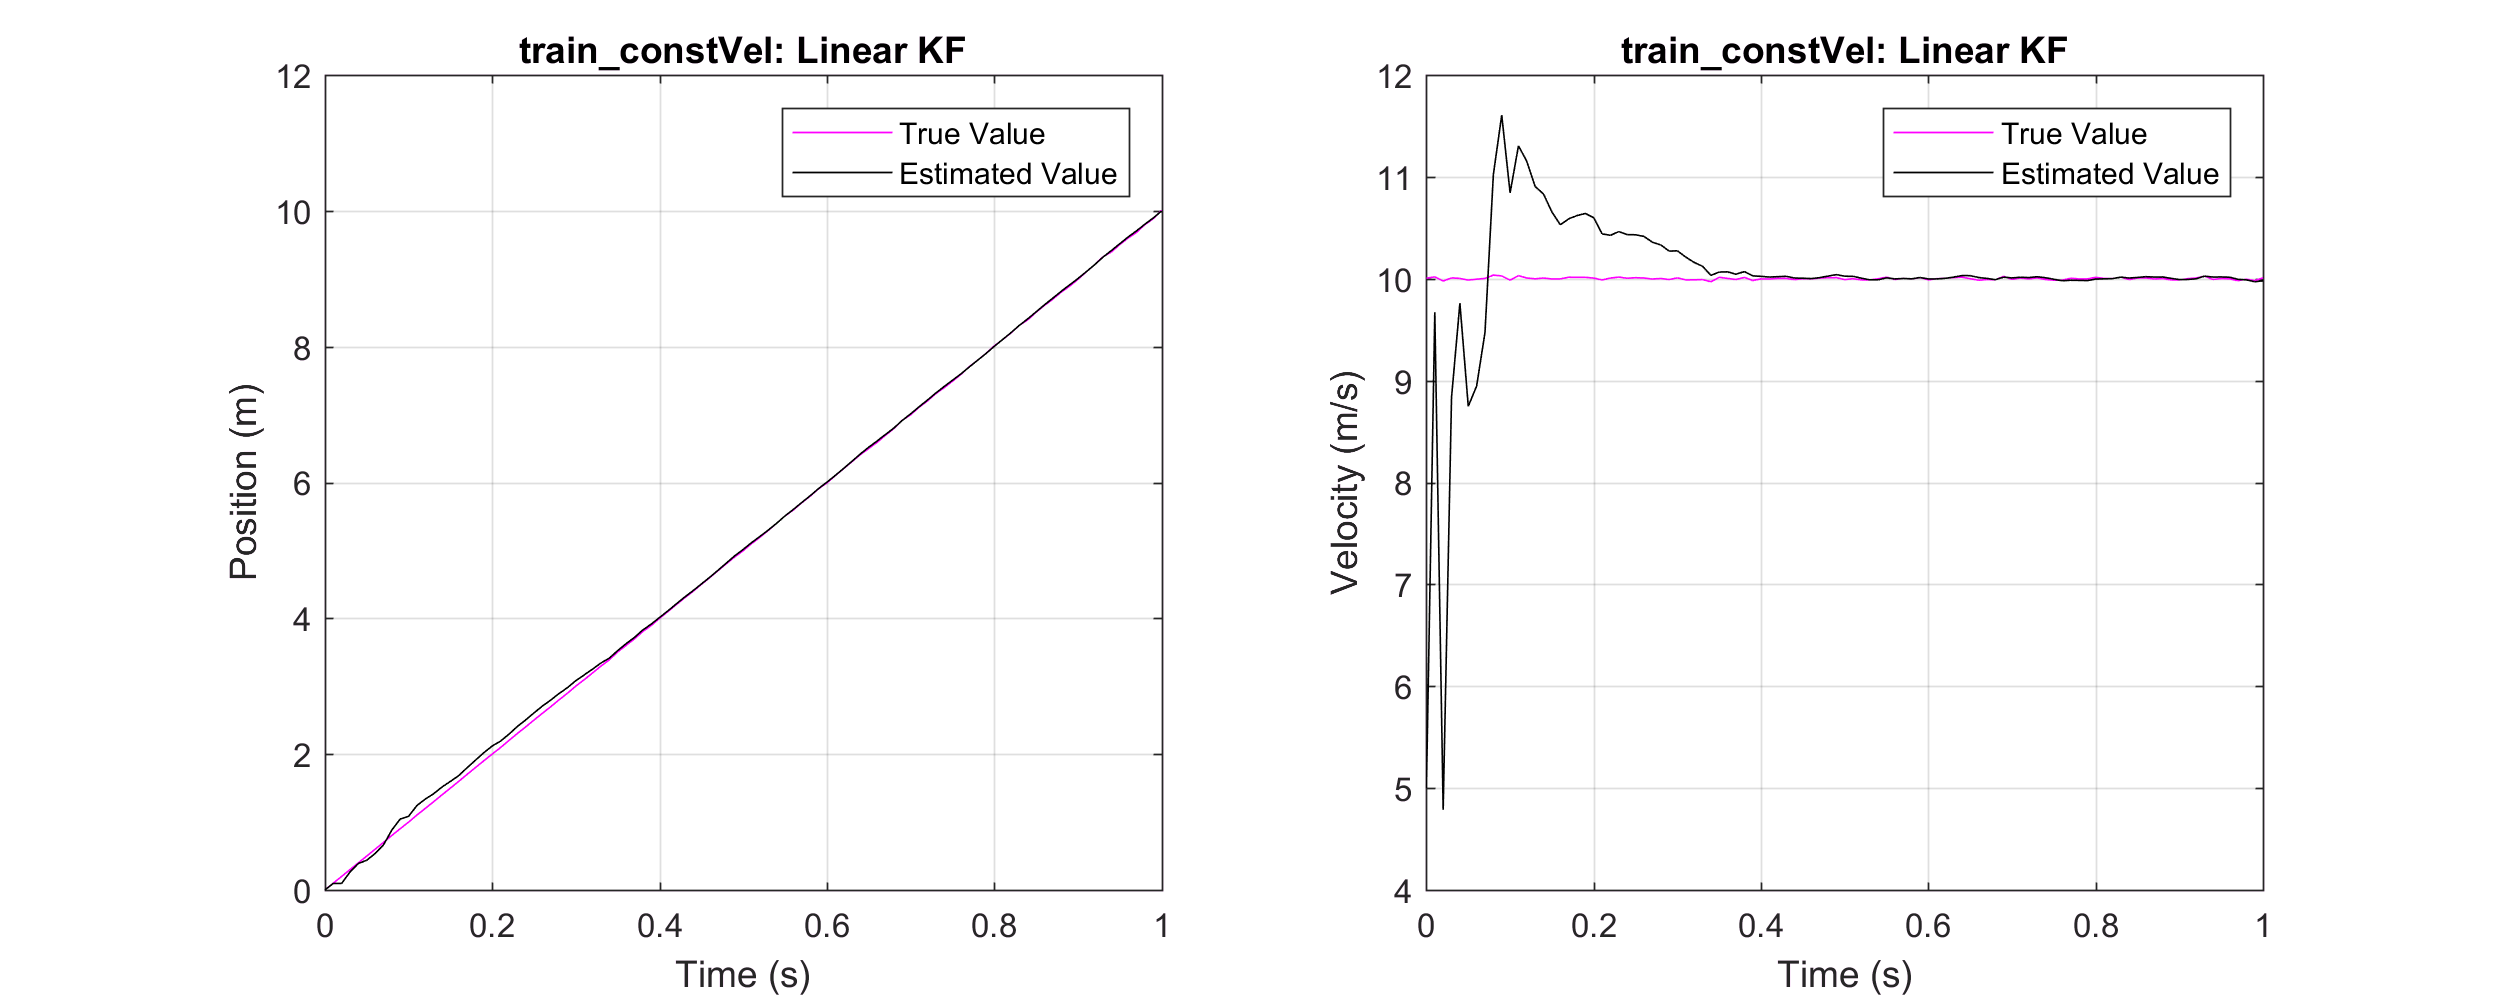

open('LinearKalmanFilter.fig')
set(gcf,'Position',[0 0 1000 400]);

After initially having poor estimates of velocity, due to our erroneous initial condition for velocity, the filter converges at roughly 0.4 seconds, and tracks the states of the system very accurately thereafter. I think this is pretty astonishing, and I hope that this motivates you to want to look under the cover and understand how Kalman filters work and how to use them. This will be the focus of the rest of this tutorial, starting with the linear Kalman filter, which was utilised in the above example.

# Linear Kalman Filter

So, we have seen the power of the linear Kalman filter (KF). Let's look at the algorithms, understand the terminology and get to grips with how it all works from one time step to the next:

## Linear Kalman Filter (KF) Equations

**1: Compute the predicted mean and covariance matrix:**

Computing the predicted mean: $\hat{x}_{k|k-1} = F\hat{x}_{k-1|k-1$ 

Computing the predicted covariance matrix: $P_{k|k-1} = FP_{k-1|k-1}F^T + Q_k$

**2: Compute the predicted measurement, innovation covariance matrix, and Kalman gain:**

Computing the predicted measurement: $\hat{y}_{k|k-1} = Hx_{k|k-1}$

Computing the innovation covariance matrix: $S_k = HP_{k|k-1}H^T + R_k$

Computing the Kalman gain: $K_k = P_{k|k-1}H^TS_K^{-1}$

**3: Compute the posterior mean and covariance matrix:**

Computing the posterior mean: $\hat{x}_{k|k} = \hat{x}_{k|k-1}  + K_k(y_k - \hat{y}_{k|k-1})$

Coimputing the covariance matrix: $P_{k|k} = P_{k|k-1} - K_kH_kP_{k|k-1}$

## Linear Kalman Filter (KF) Terminology

This algorithm may look complex, but it can be easily implemented in only 7 lines of code so don't be put off. Let's demistify it slightly now by understanding some of the terms:

- $x_{k|k-1}$: This is the predicted state vector for this new time step, $k$,  based on the information from the previous time step, $k-1$.

- $\hat{x}_{k|k-1}$: This is our estimate of the predicted state $x_{k|k-1}$, which is the output of the filter. *Calculating this accurately is the purpose of the Kalman Filter*.

- $F$: This is known as the state transition matrix, which captures our model of the system dynamics. This was introduced in our simple example above, acting as a linear mapping between the current state vector and the next state vector.

- $H$: This is known as the measurement matrix, which captures our model of the measurements. This was introduced in our simple example above, acting as a linear mapping between the current state vector and the current measurement estimate.

- $P$:

- $Q$:

- $R$:

- $S$:

- 
$$K$$
:

addpath(genpath(pwd))

%% Set General Parameters %%%%%%%%%%%%%
NSamples=100; % Number of sample steps to simulate over
dt = 0.01; % Time step between samples, s

%% Ground Truth & Model %%%%%%%%%%%%%%%
s = train_constVel(NSamples,dt); % Set up a system of a train travelling at a constant velocity
d = model_train_constVelKF(s,dt); % Set up a KF model for the system

%% Linear Kalman Filter %%%%%%%%%%%%%%%
for k=2:NSamples+1
    % Compute the predicted mean, d.X1
    d.X1 = d.F * d.X(:,k-1);
    % Compute the predicted covariance matrix, d.P1
    d.P1 = (d.F * d.P * d.F') + d.Q;
    
    % Compute the predicted measurement, d.Y1
    d.Y1 = d.H * d.X1;
    % Compute the innovation covariance matrix, d.S
    S = (d.H * d.P1 * d.H') + d.R;
    % Compute the Kalman gain (K large -> more weight goes to measurement)
    K = (d.P1 * d.H' / S);
    
    % Compute the posterior mean, d.X
    d.X(:,k) = d.X1 + (K * (s.Y(:,k) - d.Y1));
    % Compute the covariance matrix, d.P
    d.P = d.P1 - (K * d.H * d.P1);
end

%% Plot resulting graphs %%%%%%%%%%%%%%
figure;
for i = 1:s.NState
    subplot(1,2,i);
    plot(s.t,s.X(i,:),'m');
    hold on; grid on;
    plot(s.t,d.X(i,:),'k');
    title(['Estimation Results: ' s.stateString{i}]);
    xlabel(s.tString);
    ylabel(s.stateString{i});
    legend('True Value','Estimated Value');
    t = title([s.modelString ': ' d.typeString]);
    set(t, 'Interpreter', 'none');
end
set(gcf,'Position',[0 0 1000 400]);